addpath('Kinematics')
addpath('Kinetics')

supressed_print= evalc('run Ball_Plate_Kinetics_Newton_Euler.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

# Linearize the Equations Of Motion

Here, we will plug in the estimated numerical parameters of the system (figure 5) and Linearize about the unstable equilibrium point. The equilibrium point is, fortunately, characterized by a zeroing of the state vector - the plate perfectly horizontal and the ball centered on the plate. We will also have to linearize the input torques. 

## Best Current Estimates of Numerical System Parameters

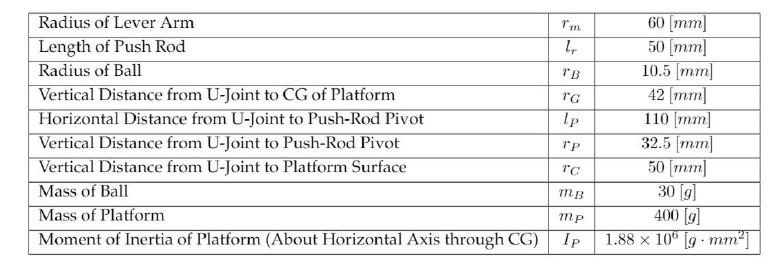

Figure 5: Estimated numerical parameters of the system.

rB = .0105; %[m]
rG = .042; %[m]
rC = .050; %[m]
mB = .030; %[kg]
mP = .400; %[kg]
IP = 1.88e6*(1/1000)*(1/1000)^2; %[kg*m^2]
IB = (2/5)*mB*rB^2;%ball inertia [kg-m^2] 
g_num = 9.81; %[m/s^2]

Num_Params = [rB  rC+rB mB mP IP IB g_num rG];
Sym_Params = [r_b z_b m_b m_p I_p__xx I_b g z_p];

## Final Assumptions

We are going to assume that the angular velocity of the ball in the z direction, $\psi_z$, is insignificant and set it to zero. We will also assume that the rate of change of this angular velocity, $\dot\psi_z$, is zero. These should prove to be very accurate assumptions because the plate does not have the ability to impart a "spinning" force on the ball through its contact patch with the plates surface. The ball's spin will remain relatively close to zero so long as its initial spin is very close to zero. 

Assumption_Params = [psi_dot_z psi_z];
Assumptions = [0 0];

Substituting known numerical parameters and our assumptions into the symbolic equations of motion:

NumEOMs = subs(SolvedEOMs, [Sym_Params Assumption_Params], [Num_Params  Assumptions]);

## Jacobian Linearization of the Numerical EOMs

The Jacobian of the equations of motion with respect to the state vector is taken. 

J_states(stateVec) = jacobian(rhs(NumEOMs), stateVec);

The Jacobian of the equations of motion with respect to the input vector is taken. The input vector is chosen to be $\tilde{u} = [T_\beta ~T_\gamma]^T$.

J_input(stateVec) = jacobian(rhs(NumEOMs),inputVec);

## Form the State Space Model 

The linearization allows us to formulate the system as a linear time invariant system of first order differential equations - this state space formulation is


$$\dot{\tilde{x}} = A\tilde{x} + B\tilde{u}$$
 

where $\tilde{x} = [x ~y ~\beta ~\gamma~\dot{x}~\dot{y}~\dot{\beta}~\dot{\gamma}]^T$ and $\tilde{u} = [T_\beta ~T_\gamma]^T$.

A = [zeros(4),eye(4);J_states(0,0,0,0,0,0,0,0)];
B = [zeros(4,2);J_input(0,0,0,0,0,0,0,0)];

The resultant system in terms of the numerical values is


$$\left\lbrack \begin{array}{c}

\dot{x}\\ \dot{y}\\ \dot{\beta}\\ \dot{\gamma}\\ 
\ddot{x}\\ \ddot{y}\\ \ddot{\beta}\\ \ddot{\gamma}

\end{array}\right\rbrack 

=

\left\lbrack \begin{array}{cccccccc}
0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\
-5.2170 & 0 & 4.0111 & 0 & 0 & 0 & 0 & 0\\
0 & -5.2170 & 0 & -4.0111 & 0 & 0 & 0 & 0\\
112.8871 & 0 & 64.8295 & 0 & 0 & 0 & 0 & 0\\
0 & -112.8871 & 0 & 64.8295 & 0 & 0 & 0 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

x\\ y\\ \beta\\ \gamma\\ 
\dot{x}\\ \dot{y}\\ \dot{\beta}\\ \dot{\gamma}

\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
0 & 0\\
-17.7268 & 0\\
0 & 17.7268\\
383.5785 & 0\\
0 & 383.5785
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}
T_{\beta }\\
T_{\gamma }
\end{array}\right\rbrack$$


It is a bit difficult to visualize immediately, but this eighth order system has been decoupled into two fourth order systems through the linearization process. The state space model can be rewritten with a reformulated state vector $\tilde{x} = [x  ~\beta ~\dot{x}~\dot{\beta}~y~\gamma~\dot{y}~\dot{\gamma}]^T

$ to better show that it's decoupled.

A_uc = [A(:,1),A(:,5),A(:,3),A(:,7),A(:,2),A(:,6),A(:,4),A(:,8)];
A_uc = [A_uc(1,:);A_uc(5,:);A_uc(3,:);A_uc(7,:);A_uc(2,:);A_uc(6,:);A_uc(4,:);A_uc(8,:)];
B_uc = [B(1,:);B(5,:);B(3,:);B(7,:);B(2,:);B(6,:);B(4,:);B(8,:)];


$$\left\lbrack \begin{array}{c}

\dot{x}\\ \ddot{x}\\ \dot{\beta}\\ \ddot{\beta}\\

\dot{y}\\ \ddot{y}\\ \dot{\gamma}\\  \ddot{\gamma}

\end{array}\right\rbrack

=

\left\lbrack \begin{array}{cccccccc}
0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\
-5.2170 & 0 & 4.0111 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\
112.8871 & 0 & 64.8295 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & -5.2170 & 0 & -4.0111 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & -112.8871 & 0 & 64.8295 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

x\\ \dot{x}\\ \beta\\ \dot{\beta}\\

y\\ \dot{y}\\ \gamma\\  \dot{\gamma}

\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{cc}
0 & 0\\
-17.7268 & 0\\
0 & 0\\
383.5785 & 0\\
0 & 0\\
0 & 17.7268\\
0 & 0\\
0 & 383.5785
\end{array}\right\rbrack


\left\lbrack \begin{array}{c}
T_{\beta }\\
T_{\gamma }
\end{array}\right\rbrack$$


## Output Equation

We are interested in controlling the entire state vector to zero, so ideally, the output to state coupling matrix should be the identity. This is only possible if it is conceivable to measure the entire state vector - in our case, with the following measurement methods, it is not:

- The u-joint angles $\beta$ and $\gamma$ can be measured with an optical encoder. These measurments, however, would need to be differentiated in order to get the estimates of $\dot\beta$ and $\dot\gamma$ - a process of state observation. 

- The $x$ and $y$ locations along the plate's surface of the ball are measurable using the touch pad attached to the plate. The $x$ and $y$ states are therefore outputs of our system.  

We will assume that the output to input coupling matrix is zero since we are not interested in having the actuation torques as feedback, nor are we interested in constructing an observer using the applied torque as an output. We also will assume unity measurement gain on the entire state vector $\beta$,$\gamma$,$x$ and $y$ states, but this does not influence the output equation. The output equation $\tilde{y} = C\tilde{x} + D\tilde{u}$ becomes:


$$\left\lbrack \begin{array}{c}
x\\
y\\
\beta \\
\gamma 
\end{array}\right\rbrack

= 

\left\lbrack \begin{array}{cccccccc}
1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 1 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}

x\\ \dot{x}\\ \beta\\ \dot{\beta}\\

y\\ \dot{y}\\ \gamma\\  \dot{\gamma}

\end{array}\right\rbrack

+ 

\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack

\left\lbrack \begin{array}{c}
T_{\beta } \\
T_{\gamma } 
\end{array}\right\rbrack$$


%Define these symbolic quantities for use by the program:
y_vec = [x y beta gamma].';
C = sym([1 0 0 0 0 0 0 0;0 0 1 0 0 0 0 0;0 0 0 0 1 0 0 0;0 0 0 0 0 0 1 0]);
D = sym(zeros(4,2));  

## Find the System Transfer Function

Assuming that we have designed an observer for the system that grants us access to the entire state vector, the new observed output vector $y_{obs}$, will be the state vector $x$ and the C matrix, $C_{obs}$ will be the identity. The D matrix will change as well to reflect the higher dimensionality of the output: 


$$\tilde{y}_{obs} = C_{obs}\tilde{x} + D_{obs}\tilde{u}$$


The system transfer function can be found using the formula $TF = C_{obs}(sI - A)^{-1}B + D_{obs}$, and it reflects eight different nonzero input to output relationships, one for each of the states in $x$.

C_obs = eye(8);
D_obs = sym(zeros(8,2));
syms s;
TF = C_obs*(s*eye(8) - A_uc)\B_uc + D_obs;


%Getting the normalized denominators for latex display of TF
[n1,d1] = numden((TF(1,1)));
[n2,d2] = numden((TF(2,1)));
n2 = expand(n2);
[n3,d3] = numden((TF(3,1)));
[n4,d4] = numden((TF(4,1)));


den_coeffs1 = coeffs(d1,s,'All');
den_coeffs2 = coeffs(d2,s,'All');
den_coeffs3 = coeffs(d3,s,'All');
den_coeffs4 = coeffs(d4,s,'All');

norm_num_1 = (n1/den_coeffs1(1));
norm_den_1 = (d1/den_coeffs1(1));

norm_num_2 = (n2/den_coeffs2(1));
norm_den_2 = (d2/den_coeffs2(1));

norm_num_3 = (n3/den_coeffs3(1));
norm_den_3 = (d3/den_coeffs3(1));

norm_num_4 = (n4/den_coeffs4(1));
norm_den_4 = (d4/den_coeffs4(1));

[n5,d5] = numden((TF(5,2)));
[n6,d6] = numden((TF(6,2)));
n6 = expand(n6);
[n7,d7] = numden((TF(7,2)));
[n8,d8] = numden((TF(8,2)));


den_coeffs5 = coeffs(d5,s,'All');
den_coeffs6 = coeffs(d6,s,'All');
den_coeffs7 = coeffs(d7,s,'All');
den_coeffs8 = coeffs(d8,s,'All');

norm_num_5 = (n5/den_coeffs5(1));
norm_den_5 = (d5/den_coeffs5(1));
norm_num_6 = (n6/den_coeffs6(1));
norm_den_6 = (d6/den_coeffs6(1));
norm_num_7 = (n7/den_coeffs7(1));
norm_den_7 = (d7/den_coeffs7(1));
norm_num_8 = (n8/den_coeffs8(1));
norm_den_8 = (d8/den_coeffs8(1));


$$\left\lbrack \begin{array}{c}

x\\ \dot{x}\\ \beta\\ \dot{\beta}\\

y\\ \dot{y}\\ \gamma\\  \dot{\gamma}

\end{array}\right\rbrack

=


\left\lbrack \begin{array}{cc}

\frac{-17.7268\,s^2 +\text{2.6878e+03}}{s^4 -59.6125\,s^2 -791.0163} & 0\\

\frac{-17.7268\,s^3 +\text{2.6878e+03}\,s}{s^4 -59.6125\,s^2 -791.0163} & 0\\

\frac{383.5785\,s^2}{s^4 -59.6125\,s^2 -791.0163} & 0\\

\frac{383.5785\,s^3}{s^4 -59.6125\,s^2 -791.0163} & 0\\

0 & \frac{17.7268\,s^2 -\text{2.6878e+03}}{s^4 -59.6125\,s^2 -791.0163}\\

0 & \frac{17.7268\,s^3 -\text{2.6878e+03}\,s}{s^4 -59.6125\,s^2 -791.0163}\\

0 & \frac{383.5785\,s^2}{s^4 -59.6125\,s^2 -791.0163}\\

0 & \frac{383.5785\,s^3}{s^4 -59.6125\,s^2 -791.0163}

\end{array}\right\rbrack



\left\lbrack \begin{array}{c}
T_{\beta }^{(1)} \\
T_{\gamma }^{(1)} 
\end{array}\right\rbrack$$
